# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 이강희**

**학번**** : 201710956**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/kangdol2/HW2_201710956_.git**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

xn을 통해 IDFT를 하여 원래 xn이 나옴을 확인 할 수 있고 그래프를 통해 DFT와 DTFT의 크기는 같다는 것을 확인 할 수 있습니다.

x1 = [1, 2, 2, 1];
N1 = length(x1);
n1 = 0:N1-1;
k1 = 0:N1-1;
WN1 = exp(-j*2*pi/N1);
nk1 = n1'*k1;
WNnk1 = WN1 .^ nk1;
Xk1 = x1 * WNnk1;
magXk1 = abs(Xk1); angleXk1 = angle(Xk1) *180 / pi;

xn1 = (Xk1 * WNnk1)/N1

xn1 =    1.0000 - 0.0000i   1.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i


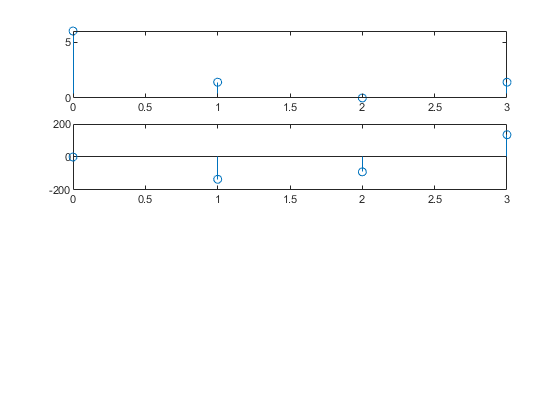


kT = -100:100;
w1 = (pi/50) * kT;
X1 = x1 * (exp(-j*pi/50)) .^ (n1'*kT);
magX1 = abs(X1); angleX1 = angle(X1);
subplot(4,1,1)
stem(n1,magXk1)
subplot(4,1,2)
stem(n1,angleXk1)

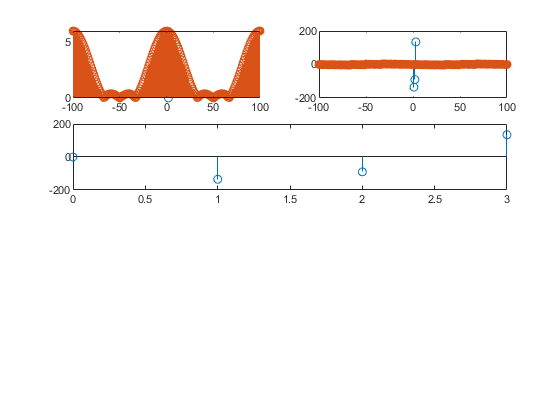


subplot(4,2,1)
stem(n1,magXk1); hold on;
stem(kT,magX1)
subplot(4,2,2)
stem(n1,angleXk1); hold on;
stem(kT,angleX1)

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

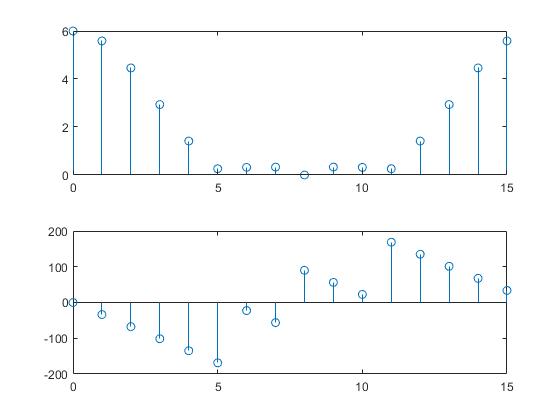

x2 = [1, 2, 2, 1, zeros(1,12)];
N2 = length(x2);
n2 = 0:N2-1;
k2 = 0:N2-1;
WN2 = exp(-j*2*pi/N2);
nk2 = n2'*k2;
WNnk2 = WN2 .^ nk2;
Xk2 = x2 * WNnk2;
magXk2 = abs(Xk2); angleXk2 = angle(Xk2) *180 / pi;
subplot(2,1,1)
stem(n2,magXk2)
subplot(2,1,2)
stem(n2,angleXk2)

xn2 = (Xk2 * WNnk2)/N2

xn2 =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 - 0.0000i   2.0000 - 0.0000i   2.0000 - 0.0000i


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

x3 = [4, 1, -1, 1];
N3 = 4;
n3 = [0:1:N3-1];
k3 = [0:1:N3-1];
WN3 = exp(-j*2*pi/N3);
nk3 = n3'*k3;
WNnk3 = WN3 .^ nk3;
X3 = x3 * WNnk3

X3 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

x4 = [1, 0, -1, -1, 0];
N4 = 5;
n4 = [0:1:N4-1];
k4 = [0:1:N4-1];
WN4 = exp(-j*2*pi/N4);
nk4 = n4'*k4;
WNnk4 = WN4 .^ nk4;
X4 = x4 * WNnk4

X4 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

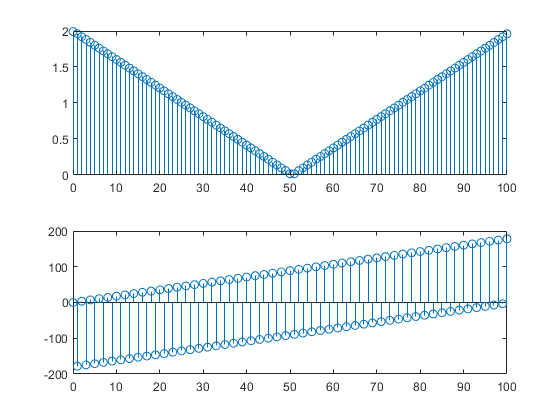

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
k = 0:N-1;
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
magXk = abs(Xk); angleXk = angle(Xk) *180 / pi;
subplot(2,1,1)
stem(n,magXk)
subplot(2,1,2)
stem(n,angleXk)

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

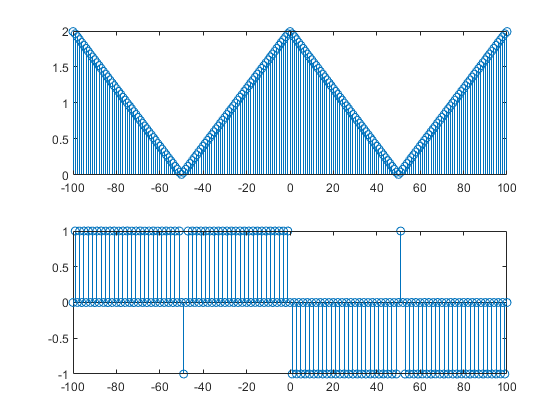

n = 0:100;
x = sinc((n-50)/2).^2;
k = -100:100;
w = (pi/50) * k;
X = x * (exp(-j*pi/50)) .^ (n'*k);
magX = abs(X); angleX = angle(X);
subplot(2,1,1)
stem(k,magX)
subplot(2,1,2)
stem(k,angleX/pi)

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

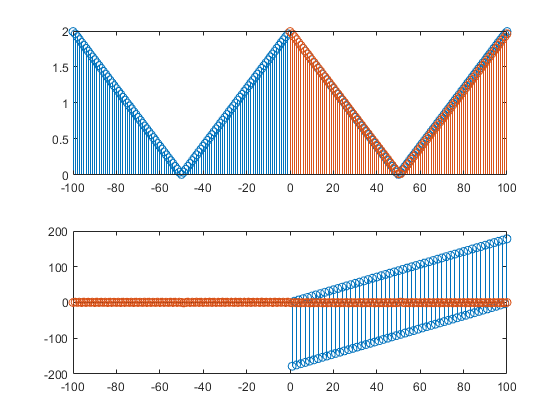


subplot(2,1,1)
stem(k,magX); hold on;
stem(n,magXk)
subplot(2,1,2)
stem(n,angleXk); hold on;
stem(k,angleX/pi)

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

크기의 경우 DFT의 길이가 DTFT와 같다면 재구성 할 수 있습니다. 위상의 경우 보간을 통해 재구성하여야 합니다.